# Tutorial do lab "Interpolacja i aproksymacja"  część 1 (interpolacja)

Zakres ćwiczenia: interpolacja i aproksymacja wielomianowa, interpolacja trygornometryczna (transformata Fouriera)

Potrzebne funkcje MATLABA: **polyfit, polyval, spline, interp1, interpft, fft, norm**. Jak zwykle potrzebne bedą również funkcje graficzne (**plot, legend**). W trakcie ćwiczenia wymagane będzie świadome korzystanie z tych funkcji (oczywiście z dostępem do dokumentacji MATLABA -** help**). Bardzo zalecane jest zapoznanie się z dokumentacją tych funkcji przed ćwiczeniem - zawiera ona sporo ilustracyjnych przykładów (również dostępnych w postaci Live Scripts).

**Uwaga**:  tutorial zawiera pytania kontrolne *'do samodzielnej odpowiedzi'*.  Bardzo ważna, i na pewno przydatna do zrozumienia zakresu tutorialu jest  świadomość jakie są prawidłowe odpowiedzi i dlaczego (pomoc: materiały wykładowe). 

#### Zalecany sposób wykonania programu z niniejszego tutoriala:

1) Wybrać z górnego paska opcję VIEW->Clear all output, a następnie VIEW-> Hide Code

2) Wybrać odpowiednie parametry programu :

  - aktywacja (opcjonalna)** Przykładu 1** poprzez wybór funkcji (menu rozwijane), rodzaju interpolacji (checkboxy, można zaznaczyć więcej niż 1) i określenie liczby węzłów (suwak)

  - aktywacja (opcjonalna) **Przykładu 2** poprzez zaznaczenie właściwego Checkboxa

3) Uruchomić program wciskając przycisk WYKONAJ w polu edytora

4) Obejrzeć świadomie wyniki, 

5) Powtórzyć punkty 2-4 dla różnych wariantów zadania

6) Przeanalizować kod (zmienić opcję VIEW)

clc;clear all;close all % to dobry poczatek kazdego skryptu
disp('Start')

Start


 % RUN tutorial

Interpolacja funkcji - jak wiadomo - polega na skonstruowaniu funkcji zadanej klasy (np. wielomianu lub sumy częściowej szeregu funkcji trygonometrycznych) przechodzącej przez znane punkty (węzły interpolacji). W celach laboratoryjnych, gdy głównym celem jest badanie własności numerycznych algorytmów, czesto wygodnie jest posługiwać się węzłami określonymi przez z góry zadaną funkcję - żeby łatwo zilustrować dokładność odtworzenia funkcji oryginalnej przez funkcję interpolującą (należy jednak pamiętać, że prawdziwy problem interpolacji pojawia się gdy nie znamy postaci analitycznej funkcji, na której leżą węzły, albo gdy koszt policzenia znanej funkcji jest bardzo duży).  

Błąd interpolacji definiowany jest zwykle jako maksymalna odległość funkcji oryginanej i funkcji interpolującej - i taka miara jest przyjęta w przykładowych kodach (ale można określać dokładność interpolacji za pomocą innej miary błędu). 

 *Pytanie kontrolne do samodzielnej odpowiedzi :  czy niedokładność interpolacji jest określana  w węzłach?  *

Dokładność interpolacji zależy od przybliżanej funkcji oraz od wyboru węzłów interpolacji.

*Pytanie kontrolne do samodzielnej odpowiedzi :  w jaki sposób należy wybierać węzły interpolacji, żeby dokładność interpolacji była maksymalna*?

Do interpolacji wielomianowej służą funkcje MATLABA: **polyfit, polyval, spline (lub interp1)**. Specjalnym przypadkiem jest interpolacja funkcją odcinkowo-liniową, realizowana jako domyślny wariant przez funkcję MATLABA **interp1.**

 *Pytanie kontrolne do samodzielnej odpowiedzi :  na czym polega interpolacja funkcją sklejaną ?*

Do interpolacji trygonometrycznej tzn. przybliżania funkcji za pomocą transformaty Fouriera służy funkcja MATLABA **interpft**.

*Pytanie kontrolne do samodzielnej odpowiedzi : Dla jakich funkcji stosuje się interpolację trygonometryczną? Co jest argumentem kolejnych składników szeregu Fouriera używanych przez ****interpft****?*

### Przykład 1. Interpolacja wielomianowa i trygonometryczna

Przykład 1 ilustruje różne metody interpolacji na zestawie dwóch funkcji. Zestaw funkcji i sposób/sposoby interpolacji należy wybrać we właściwych polach

 % Przykład 1
Ng=300; % przykładowa liczba punktów 'gestej' dziedziny
fun=2;
switch fun
    case 1
        f1=@(x) exp(x) ; f1a=@(x) exp(abs(x));a1=-1;b1=2; 
    case 2
        f1=@(x) sqrt(x.^2+1) ; f1a=@(x) 1./sqrt(1+x.^2);a1=-3;b1=3;
    case 3
        f1=@(x) sin(2*x) ; f1a=@(x) cos(2*(x.^2));a1=0;b1=2*pi;
    case 4
        f1=@(x) log(x) ; f1a=@(x) abs(log(x));a1=0.1;b1=10;
end
 

Wybierz  sposób interpolacji (minimum jeden, mogą być wszystkie)

I(1)=false;% wezly rownoodlegle, wielomian odpowiedniego stopnia
I(2)=false;% wezly Czebyszewa, wielomian odpowiedniego stopnia
I(3)=false;% wezly rownoodlegle, spline
I(4)=false;% wezly rownoodlegle, interpolacja trygonometryczna

 *Pytanie kontrolne do samodzielnej odpowiedzi : Czym są węzły Czebyszewa ?*

Wybierz liczbę węzłów interpolacji wielomianowej

   Nw=10

Nw = 10

 Uwaga: Jeśli wybrano interpolację trygonometryczną, liczba uzytych węzłów będzie o 1 mniejsza (*dlaczego?*) 

*Pytanie kontrolne kontrolne do samodzielnej odpowiedzi: Jaki jest 'odpowiedni' stopień wielomianu ?*


if (I(4) && fun~=3)
    error('Zly dobór funkcji i sposobu interpolacji')
end
if (sum(I))
    leg_str=[];fig_nr=1;
    err1=plotsingle(f1,a1,b1,Nw,I,Ng,fig_nr,leg_str);
    err1a=plotsingle(f1a,a1,b1,Nw,I,Ng,fig_nr+1,leg_str);
end


**Uwaga: **można przenieść dowolny rysunkek powstały po wykonaniu tego kodu do 'zwykłego' okna graficznego - w tym celu należy najechać myszką na rysunek i wybrać opcję '`Open in figure window`' - strzałka w prawym górnym rogu. W oknie graficznym można np. dokywać edycji rysunku (`Edit` w górnym pasku narzędzi) - usuwać niektóre dane, zmieniać kolory, format linii etc. Można też dokonać automatycznego dopasowania funkcji wielomianowej wybranego stopnia do funkcji oryginalnej (pasek narzędzi na górze rysunku `Tools-> Basic fitting` -> wybór stopnia wielomianu w nowootwartym oknie). *Czy to będzie interpolacja*? 

Jeśli chcesz powtórzyć eksperyment w innej konfiguracji (z innymi funkcjami lub liczbą węzłów czy sposobem interpolacji), dokonaj stosownych zmian w ustawieniach  i ponownie przyciśnij przycisk WYKONAJ.

Po wykonaniu zadania warto zauważyć (i zastanowić się dlaczego tak jest), że

1) Czasami wykresy nakładają się na siebie (na pewno wszystkie wykresy opisane legendą znajdują się na rysunku!). Każdy kolejny wykres jest rysowany coraz 'rzadszą' linią  od ciągłej do kropkowanej, ale i tak czasem nie da się rozróżnić wszystkich wykresów. 

2) Zdarza się, że wykresy się nakładają, a odpowiadające im błędy interpolacji różnią się o kilka rzędów wielkości.

3) Relacje między błędami otrzymanymi dla węzłów równoodległych przy interpolacji wielomianem odpowiednio wysokiego stopnia i przy interpolacji splinem są różne -  czasami dokładniejsza jest jedna, a czasami druga metoda.

4) Nie zawsze zwiekszenie liczby węzłów skutkuje zmniejszeniem błędu interpolacji. Zdarza się, że przy interpolacji wielomianem odpowiednio wysokiego stopnia występują spore oscylacje między węzłami, szczególnie w pobliżu końców przedziału. *Jak nazywa się ten efekt?* Warto też zwrócić uwagę, że występuje on również przy (niektórych!) gładkich funkcjach! Warto też skojarzyć otrzymane wyniki z wlasnością zwaną zbieżnością interpolacji. *Pytanie kontrolne do samodzielnej odpowiedzi co to jest zbieżność interpolacji?*

5) Czasami w wyniku wykonania kodu otrzymuje się (czerwony) tekst ostrzeżenia: 

`Warning: Polynomial is badly conditioned. Add points with distinct X values, reduce the degree of the polynomial, or try centering and scaling as described in HELP POLYFIT`.

Pomimo tego ostrzeżenia (zwykle) interpolacja została wykonana poprawnie.* Połącz taki wynik działania kodu z wiadomościami z wykładu ***oraz z zadaniem z  Przykładu 2.**

6) Przy samodzielnych eksperymentach (raczej nie w wyniku wykonywania tego kodu)  może się też zdarzyć, że otrzyma się (czerwony) tekst ostrzeżenia

`Warning: Polynomial is not unique; degree >= number of data points. `

To ostrzeżenie ma już inny charakter i świadczy o błędnym wykonaniu zadania. *Dlaczego?*

### Przykład 2. Skalowanie i centrowanie. Ekstrapolacja.

To zadanie jest oparte na przykładzie  z dokumentacji MATLABa    (patrz np. Live Scripts  **UseCenteringAndScalingToImproveNumericalPropertiesExample.mlx, LiveEditorIntroduction.mlx**)

Dana jest populacja USA w latach 1750 - 2000. Na tej podstawie, używając interpolacji wielomianowej, należy przewidzieć populację w roku 2010. 

Ex2=true

Ex2 = logical
   1


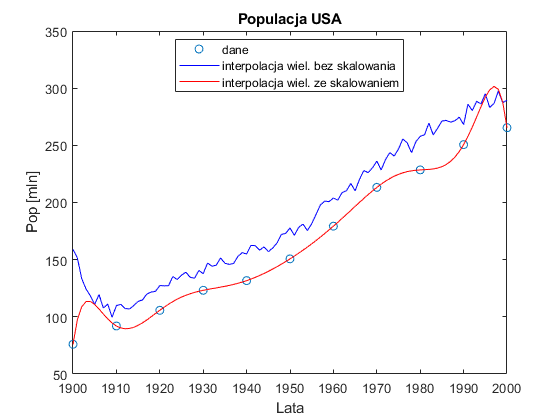

predict2010_int = 172.1250

predict2010_intskal = -2.2959e+03

predict2010_spline = 244.1468

predict2010_linear = 280.2110

if Ex2
    year = (1900:10:2000); evyear=1900:2000;                                 % Time interval
    pop = [75.995 91.972 105.711 123.203 131.669 ...        % Population Data in milions
        150.697 179.323 213.212 228.505 250.633 265.422];
    p1=polyfit(year,pop,numel(year)-1);
    [p2,~,mu] = polyfit(year, pop,numel(year)-1);
    figure
    plot(year,pop,'o',evyear,polyval(p1,evyear),'b',evyear,polyval(p2,evyear,[],mu),'r')
    legend('dane','interpolacja wiel. bez skalowania',...
        'interpolacja wiel. ze skalowaniem','Location','B')
    title('Populacja USA')
    xlabel('Lata');ylabel('Pop [mln]')
    predict2010_int=polyval(p1,2010)
    predict2010_intskal = polyval(p2,2010,[],mu)
    predict2010_spline=spline(year,pop,2010)
    predict2010_linear = interp1(year,pop,2010,'linear','extrap')
end

Oceń błąd predykcji (prawdziwy wynik to 288.42 miliony). Co sądzić metodach, które dały wyniki ujemne? Czy można co 

Oprócz własności ekstrapolacji, ten przykad ilustruje jakość interpolacji, w tym przykładzie interpolacji bez saklowania . Podkreślmy, że tym razem komunikat  ostrzeżenia  MATLABA: (`Warning: Polynomial is badly conditioned...) ` oznacza nieprawidłowe rozwiązanie zadania interpolacji bez skalowania- funkcja interpolująca nie przechodzi przez węzły.

Odpowiedź dlaczego tak jest zasadza się na porównaniu współczynnika uwarunkowania macierzy A układu równań rozwiązywanego przez zadanie interpolacji w dwóch wersjach. W zapisie **Ax=b**, **A **to macierz Vandermonda utworzona przez wektor kolejnych potęg zmiennej niezależnej (tu:* year* w wersji podstawowej lub year przeskalowane poprzez **polyfit** do formuły $x_{\textrm{skal}} =\frac{x-\mu_1 }{\mu_2 }$ ), **x** - szukany wektor współczynników wielomianu interpolującego,** y** - wektor wartości funkcji (tu: populacja).

year_skal=(year-mu(1))/mu(2);
A=vander(year');
Askal=vander(year_skal');
cond_A=cond(A)

cond_A = 6.5717e+48

cond_Askal=cond(Askal)

cond_Askal = 1.9564e+04

 Podkreślmy jeszcze raz, że  **polyfit**  ze skalowaniem - mimo, że prawidłowo rozwiązuje problem intterpolacji - nie zapewnia dobrej predykcji. *Dlaczego?*


if ~(sum(I)||Ex2)
    error('Nie wybrano żadnej akcji!')
end


function [err, leg_str]=plotsingle(f,a,b,N,I,Ng,fignr,leg_str)
 st=N-1;
xg=linspace(a,b,Ng);yg=f(xg);
xw=linspace(a,b,N);
yw=f(xw);
ys=spline(xw,yw,xg);
zC=cos(pi*(2*[1:N]-0.5)/N);
xwC=((b-a)*zC+b+a)/2;
ywC=f(xwC);
pr=polyfit(xw,yw,st);yr=polyval(pr,xg);
pC=polyfit(xwC,ywC,st);yC=polyval(pC,xg);
if I(4)
    yt=interpft(xw(1:end-1),yw(1:end-1),xg(1:end-1));
end
figure(fignr)
plot(xg,yg,'c','LineWidth',1)
L=["funkcja oryginalna","wezly rownoodlegle","wezly Czebyszewa",... 
    "wezly dla int. trygonom.","f interp. wezly rownoodl.",...
   "f interp. wezly Czeb.","f interp. spline"];
lnr=1;leg_str=[leg_str,L(lnr)];
hold on
if (I(1)||I(3))
    plot(xw,yw,'bo')
    lnr=2;leg_str=[leg_str,L(lnr)];
end
if I(2)
    plot(xwC,ywC,'kh')
    lnr=3;leg_str=[leg_str,L(lnr)];
end
if I(4)
    plot(xw(1:end-1),yw(1:end-1),'b*')
    lnr=4;leg_str=[leg_str,L(lnr)];
end
err=[];
if I(1)
    plot(xg,yr,'b--','LineWidth',2)
    lnr=5;leg_str=[leg_str,L(lnr)];
    err_r=norm(yg-yr,inf)
    err=[err,err_r];
end
if I(2)
    plot(xg,yC,'r-.','LineWidth',2)
    lnr=6;leg_str=[leg_str,L(lnr)];
    err_C=norm(yg-yC,inf)
    err=[err,err_C];
end
if I(3)
    plot(xg,ys,'k:','LineWidth',2)
    lnr=7;leg_str=[leg_str,L(lnr)];
    err_s=norm(yg-ys,inf)
    err=[err,err_s];
end
if I(4)
    plot(xg(1:end-1),yt,'b:','LineWidth',2)
    lnr=7;leg_str=[leg_str,L(lnr)];
    err_t=norm(yg(1:end1)-yt,inf)
    err=[err,err_t];
end
legend(leg_str,'Location','Best')
fname=extractAfter(func2str(f),'@(x)');
title(['Funkcja ',fname, ', ',num2str(N), ' wezlow',])
end